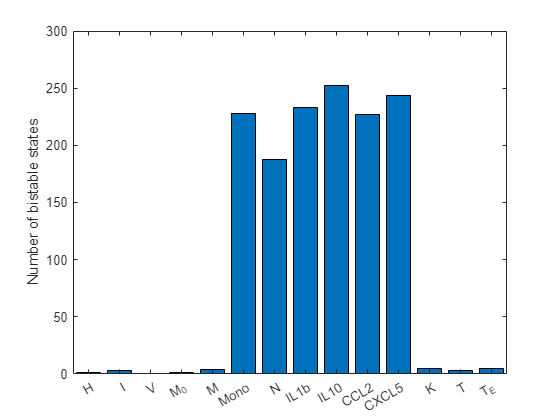

multi_ss = importdata('multi_ss_256.txt');

ss_num = zeros(14, 1);

for i = 1:14
    diff_idx = multi_ss(multi_ss(:, 2 * i + 1) ~= multi_ss(:, 2 * i + 2));
    ss_num(i) = length(diff_idx);
end

figure;
var_name = categorical({'H', 'I', 'V', 'M_0', 'M', 'Mono', 'N', 'IL1b', 'IL10', 'CCL2', 'CXCL5', 'K', 'T', 'T_E'});
var_name = reordercats(var_name, {'H', 'I', 'V', 'M_0', 'M', 'Mono', 'N', 'IL1b', 'IL10', 'CCL2', 'CXCL5', 'K', 'T', 'T_E'});
bar(var_name, ss_num);
ylabel('Number of bistable states');